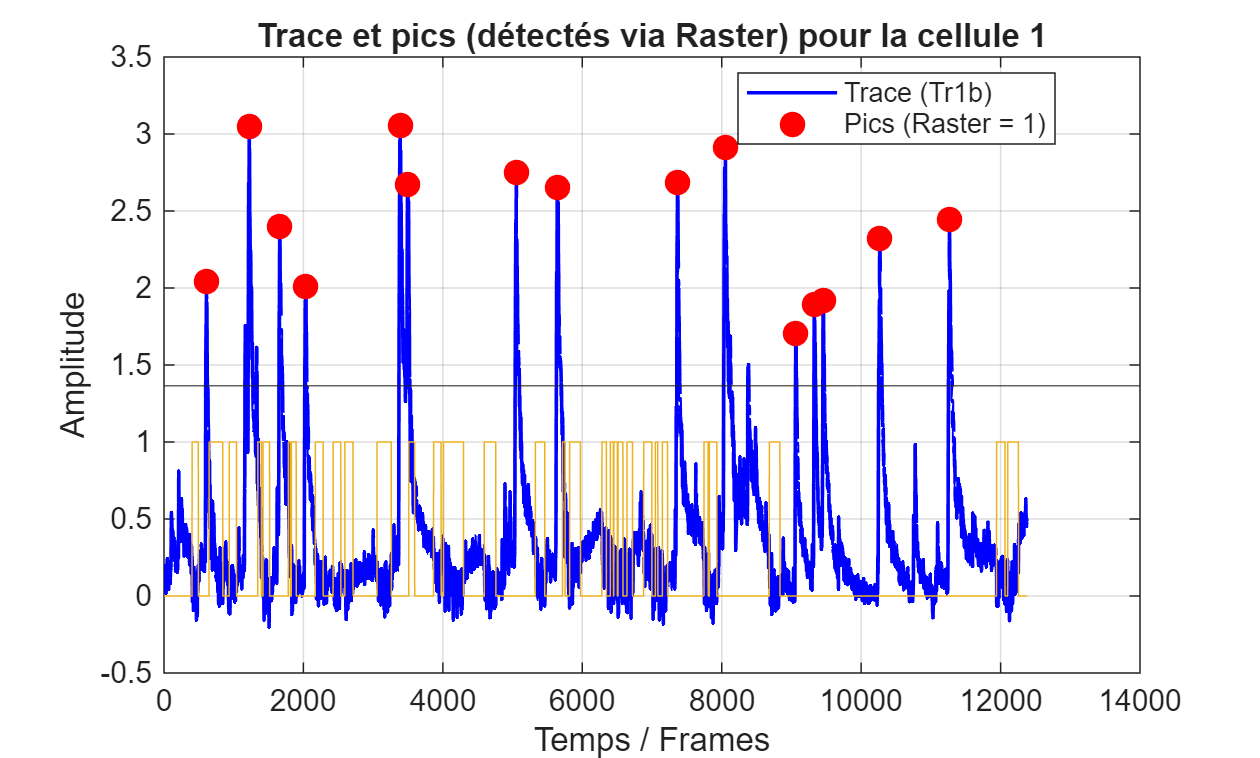

% Choisissez l'index de la cellule que vous souhaitez afficher
cell_idx = 1; 
WinActive_bin = speedsm > 2;
% 1. Trouver les indices temporels (colonnes) où le Raster vaut 1 pour cette cellule
indices_pics_raster = find(Raster(cell_idx, :) == 1);

figure;
% 2. Tracer la trace originale de la cellule (en bleu)
plot(Tr1b(cell_idx, :), 'b-', 'LineWidth', 1.2);
hold on;

% 3. Superposer les pics en utilisant les indices extraits du Raster (en rouge)
plot(indices_pics_raster, Tr1b(cell_idx, indices_pics_raster), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
yline(th(cell_idx))
plot(WinActive_bin)
hold off;

% 4. Ajouter les annotations pour la clarté
title(['Trace et pics (détectés via Raster) pour la cellule ', num2str(cell_idx)]);
xlabel('Temps / Frames');
ylabel('Amplitude');
legend('Trace (Tr1b)', 'Pics (Raster = 1)', 'Location', 'best');
grid on;